## **Visualization Differences in Coupling between Tasks**

This script is used to quantify and visualize task-dependent adaptations.  

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Create a group-average map depicting the regional SC-FC coupling pattern for each condition (do this for each condition separately) **

1.1.  Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_wm_532{i,2};% change here to switch between the 8 conditions(rest/task) 
    for j = 1:358
    Node_all_baseline_best_measures_HCP_r2{i,j} = x(j,:);
    end
end


1.2. Create a cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_best_measures_HCP_r2,2);
All_Nodes_complete_baseline_best_measures_HCP_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_r2{j} = vertcat(Node_all_baseline_best_measures_HCP_r2{:,j});
end 

1.3. Only keep 4 measures: path length (1), communicability (2), cosine distance (3) & search information (4) 

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_baseline_best_measures_HCP_r2{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i} = four_measures_per_node;
end

1.4. Collect the highest coupling value and the respective coupling measure per node 

Max_values_individuals_HCP = zeros(532,358);
Max_indices_individuals_HCP = zeros(532,358);

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};

    for p = 1:532
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2); 
        Max_values_individuals_HCP(p,i) = max_r2;
        Max_indices_individuals_HCP(p,i) = idx_max;

    end
end

1.5. Find out mode for each node (group-based mask) 

Mode_for_all_nodes = zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_HCP(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

1.6. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

Mean_values_across_all_nodes = zeros(1,358);

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);

Mean_values_across_all_nodes(1,i) = mean_per_node;

end

**2. Prepare Condition-specific vectors**

2.1. Convert cell to mat

Mean_values_across_all_nodes_wm_mat = Mean_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Mean_values_across_all_nodes_gambling_mat =     0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0292    0.0584    0.0923


min(Mean_values_across_all_nodes_wm_mat)

ans = 0.0116

max(Mean_values_across_all_nodes_wm_mat)

ans = 0.2427

2.2. Insert a 0 at node 120 & 300

a = Mean_values_across_all_nodes_wm_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_wm_360 = a

Mean_values_across_all_nodes_mat_gambling_360 =     0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0292    0.0584    0.0923


Mean_values_across_all_nodes_mat_wm_360(120) = NaN;
Mean_values_across_all_nodes_mat_wm_360(300)= NaN;

**3. Compute Distance Measures**

1. Compute mean task & mean task leave one out

all_tasks = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0292    0.0

mean_all_tasks = nanmean(all_tasks)

mean_all_tasks =     0.1489    0.0645    0.1132    0.1764    0.2000    0.2181    0.1847    0.1605    0.1435    0.0418    0.0487    0.0487    0.1914    0.0522    0.0411    0.1658    0.1008    0.1085    0.1978    0.1886    0.1885    0.1737    0.0819    0.0667    0.0548    0.0521    0.0279    0.0537    0.0356    0.0537    0.0519    0.0316    0.0583    0.0683    0.0703    0.0554    0.0509    0.0306    0.0791    0.1039    0.0605    0.1054    0.0736    0.0617    0.0722    0.0752    0.1116    0.0323    0.0646    0.0907



all_tasks_no_emotion = [Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_emotion =     0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0292    0.0584    0.0923
    0.1612    0.0790    0.1996    0.2224    0.2269    0.2559    0.2524    0.1830    0.1973    0.0758    0.0965    0.0439    0.2581    0.0562    0.0239    0.2361    0.1051    0.1252    0.2556    0.2578    0.2426    0.1968    0.1056    0.1541    0.0878    0.0468    0.0322    0.0883    0.0308    0.0418    0.0542    0.0340    0.0595    0.0750    0.0661    0.0687    0.0599    0.0280    0.0873    0.1595    0.0833    0.1339    0.1041    0.0879    0.0896    0.0752    0.1836    0.

mean_all_tasks_no_emotion = nanmean(all_tasks_no_emotion)

mean_all_tasks_no_emotion =     0.1575    0.0680    0.1234    0.1874    0.2116    0.2291    0.1973    0.1712    0.1530    0.0447    0.0532    0.0532    0.2034    0.0546    0.0420    0.1752    0.1051    0.1145    0.2099    0.2001    0.1987    0.1833    0.0865    0.0735    0.0591    0.0546    0.0291    0.0580    0.0377    0.0549    0.0540    0.0326    0.0600    0.0714    0.0724    0.0589    0.0538    0.0310    0.0843    0.1119    0.0648    0.1105    0.0797    0.0661    0.0762    0.0785    0.1180    0.0333    0.0677    0.0946



all_tasks_no_gambling = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_gambling =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1612    0.0790    0.1996    0.2224    0.2269    0.2559    0.2524    0.1830    0.1973    0.0758    0.0965    0.0439    0.2581    0.0562    0.0239    0.2361    0.1051    0.1252    0.2556    0.2578    0.2426    0.1968    0.1056    0.1541    0.0878    0.0468    0.0322    0.0883    0.0308    0.0418    0.0542    0.0340    0.0595    0.0750    0.0661    0.0687    0.0599    0.0280    0.0873    0.1595    0.0833    0.1339    0.1041    0.0879    0.0896    0.0752    0.1836    0

mean_all_tasks_no_gambling = nanmean(all_tasks_no_gambling)

mean_all_tasks_no_gambling =     0.1467    0.0639    0.1134    0.1754    0.1988    0.2168    0.1867    0.1578    0.1412    0.0428    0.0504    0.0478    0.1903    0.0524    0.0401    0.1651    0.0999    0.1095    0.2002    0.1877    0.1891    0.1747    0.0816    0.0693    0.0569    0.0524    0.0275    0.0553    0.0360    0.0528    0.0524    0.0324    0.0575    0.0678    0.0699    0.0556    0.0511    0.0306    0.0785    0.1042    0.0612    0.1049    0.0737    0.0616    0.0721    0.0757    0.1121    0.0328    0.0656    0.0905



all_tasks_no_language = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_language =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0

mean_all_tasks_no_language = nanmean(all_tasks_no_language)

mean_all_tasks_no_language =     0.1469    0.0621    0.0988    0.1688    0.1956    0.2118    0.1734    0.1567    0.1345    0.0362    0.0407    0.0495    0.1803    0.0515    0.0439    0.1540    0.1001    0.1057    0.1882    0.1771    0.1795    0.1698    0.0779    0.0521    0.0493    0.0529    0.0272    0.0479    0.0364    0.0557    0.0515    0.0312    0.0581    0.0672    0.0710    0.0532    0.0494    0.0310    0.0777    0.0946    0.0566    0.1007    0.0685    0.0573    0.0693    0.0752    0.0996    0.0308    0.0603    0.0909



all_tasks_no_motor = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_motor =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.02

mean_all_tasks_no_motor = nanmean(all_tasks_no_motor)

mean_all_tasks_no_motor =     0.1532    0.0654    0.1141    0.1813    0.2044    0.2202    0.1929    0.1627    0.1508    0.0414    0.0487    0.0477    0.1925    0.0529    0.0389    0.1672    0.1027    0.1119    0.2010    0.1916    0.1919    0.1807    0.0836    0.0691    0.0550    0.0530    0.0274    0.0544    0.0333    0.0520    0.0508    0.0325    0.0582    0.0686    0.0702    0.0567    0.0513    0.0306    0.0794    0.1093    0.0613    0.1041    0.0744    0.0621    0.0713    0.0760    0.1115    0.0325    0.0646    0.0918



all_tasks_no_relational = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_social_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_relational =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088   

mean_all_tasks_no_relational = nanmean(all_tasks_no_relational)

mean_all_tasks_no_relational =     0.1499    0.0656    0.1190    0.1783    0.1997    0.2143    0.1797    0.1600    0.1440    0.0426    0.0494    0.0464    0.1922    0.0541    0.0415    0.1635    0.0987    0.1063    0.1944    0.1820    0.1796    0.1655    0.0829    0.0692    0.0542    0.0513    0.0287    0.0532    0.0363    0.0558    0.0546    0.0320    0.0603    0.0702    0.0720    0.0559    0.0513    0.0314    0.0793    0.1060    0.0618    0.1075    0.0763    0.0620    0.0730    0.0724    0.1141    0.0327    0.0645    0.0881



all_tasks_no_social = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_wm_360]

all_tasks_no_social =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0

mean_all_tasks_no_social = nanmean(all_tasks_no_social)

mean_all_tasks_no_social =     0.1432    0.0618    0.1101    0.1714    0.1947    0.2176    0.1800    0.1578    0.1414    0.0434    0.0496    0.0489    0.1867    0.0500    0.0430    0.1735    0.1006    0.1081    0.1979    0.1965    0.1946    0.1720    0.0805    0.0659    0.0556    0.0508    0.0289    0.0554    0.0347    0.0525    0.0497    0.0305    0.0566    0.0666    0.0683    0.0535    0.0505    0.0303    0.0757    0.0988    0.0580    0.1080    0.0703    0.0638    0.0743    0.0761    0.1178    0.0322    0.0656    0.0909



all_tasks_no_wm = [Mean_values_across_all_nodes_mat_emotion_360; Mean_values_across_all_nodes_mat_gambling_360; Mean_values_across_all_nodes_mat_language_360; Mean_values_across_all_nodes_mat_motor_360; Mean_values_across_all_nodes_mat_relational_360; Mean_values_across_all_nodes_mat_social_360]

all_tasks_no_wm =     0.0977    0.0438    0.0524    0.1107    0.1305    0.1523    0.1092    0.0960    0.0862    0.0243    0.0219    0.0215    0.1195    0.0380    0.0355    0.1094    0.0748    0.0725    0.1253    0.1195    0.1273    0.1161    0.0542    0.0260    0.0287    0.0366    0.0206    0.0275    0.0235    0.0466    0.0392    0.0257    0.0478    0.0499    0.0579    0.0344    0.0338    0.0276    0.0477    0.0557    0.0345    0.0748    0.0367    0.0353    0.0482    0.0550    0.0730    0.0265    0.0455    0.0678
    0.1622    0.0681    0.1123    0.1826    0.2078    0.2258    0.1732    0.1768    0.1573    0.0360    0.0383    0.0543    0.1983    0.0511    0.0470    0.1699    0.1059    0.1024    0.1840    0.1938    0.1853    0.1674    0.0835    0.0512    0.0423    0.0501    0.0306    0.0439    0.0335    0.0594    0.0489    0.0272    0.0627    0.0711    0.0728    0.0540    0.0499    0.0300    0.0824    0.1018    0.0560    0.1084    0.0731    0.0620    0.0727    0.0720    0.1088    0.0292 

mean_all_tasks_no_wm = nanmean(all_tasks_no_wm)

mean_all_tasks_no_wm =     0.1452    0.0647    0.1138    0.1724    0.1956    0.2170    0.1830    0.1572    0.1396    0.0416    0.0490    0.0475    0.1945    0.0499    0.0382    0.1619    0.0983    0.1034    0.1933    0.1852    0.1863    0.1697    0.0801    0.0678    0.0534    0.0494    0.0266    0.0514    0.0350    0.0523    0.0502    0.0302    0.0572    0.0663    0.0686    0.0539    0.0491    0.0290    0.0786    0.1023    0.0594    0.1021    0.0723    0.0590    0.0692    0.0724    0.1080    0.0318    0.0635    0.0884


2. Compute distance between rest and task 

% Emotion
emotion_minus_rest = Mean_values_across_all_nodes_mat_emotion_360 - Mean_values_across_all_nodes_mat_rest_360

emotion_minus_rest =    -0.0589   -0.0577   -0.1244   -0.1078   -0.0961   -0.1032   -0.1956   -0.1715   -0.1619   -0.0144   -0.0278   -0.0528   -0.1103   -0.1014   -0.0509   -0.1419   -0.0385   -0.0875   -0.1555   -0.1726   -0.1592   -0.1413   -0.0598   -0.1534   -0.0257   -0.0259   -0.0395   -0.0467   -0.0618   -0.0405   -0.0639   -0.0339   -0.0443   -0.0595   -0.0527   -0.1755   -0.0658   -0.0177   -0.1828   -0.1752   -0.1037   -0.0897   -0.0875   -0.0546   -0.0478   -0.0508   -0.0730   -0.0044   -0.0205   -0.0453


emotion_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_emotion_360 - Mean_values_across_all_nodes_mat_rest_360)

emotion_minus_rest_absolut =     0.0589    0.0577    0.1244    0.1078    0.0961    0.1032    0.1956    0.1715    0.1619    0.0144    0.0278    0.0528    0.1103    0.1014    0.0509    0.1419    0.0385    0.0875    0.1555    0.1726    0.1592    0.1413    0.0598    0.1534    0.0257    0.0259    0.0395    0.0467    0.0618    0.0405    0.0639    0.0339    0.0443    0.0595    0.0527    0.1755    0.0658    0.0177    0.1828    0.1752    0.1037    0.0897    0.0875    0.0546    0.0478    0.0508    0.0730    0.0044    0.0205    0.0453



nansum(emotion_minus_rest)

ans = -28.1748

nansum(emotion_minus_rest_absolut)

ans = 28.1899


% Gambling
gambling_minus_rest = Mean_values_across_all_nodes_mat_gambling_360 - Mean_values_across_all_nodes_mat_rest_360

gambling_minus_rest =     0.0056   -0.0334   -0.0645   -0.0358   -0.0188   -0.0296   -0.1317   -0.0907   -0.0908   -0.0028   -0.0114   -0.0201   -0.0316   -0.0883   -0.0393   -0.0815   -0.0074   -0.0576   -0.0968   -0.0983   -0.1013   -0.0899   -0.0306   -0.1282   -0.0122   -0.0124   -0.0294   -0.0303   -0.0517   -0.0277   -0.0542   -0.0324   -0.0293   -0.0383   -0.0378   -0.1560   -0.0498   -0.0153   -0.1481   -0.1290   -0.0822   -0.0561   -0.0511   -0.0279   -0.0232   -0.0338   -0.0373   -0.0017   -0.0076   -0.0208


gambling_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_gambling_360 - Mean_values_across_all_nodes_mat_rest_360)

gambling_minus_rest_absolut =     0.0056    0.0334    0.0645    0.0358    0.0188    0.0296    0.1317    0.0907    0.0908    0.0028    0.0114    0.0201    0.0316    0.0883    0.0393    0.0815    0.0074    0.0576    0.0968    0.0983    0.1013    0.0899    0.0306    0.1282    0.0122    0.0124    0.0294    0.0303    0.0517    0.0277    0.0542    0.0324    0.0293    0.0383    0.0378    0.1560    0.0498    0.0153    0.1481    0.1290    0.0822    0.0561    0.0511    0.0279    0.0232    0.0338    0.0373    0.0017    0.0076    0.0208



nansum(gambling_minus_rest)

ans = -19.2881

nansum(gambling_minus_rest_absolut)

ans = 19.6975


% Language
language_minus_rest = Mean_values_across_all_nodes_mat_language_360 - Mean_values_across_all_nodes_mat_rest_360

language_minus_rest =     0.0046   -0.0226    0.0228    0.0040    0.0003    0.0004   -0.0525   -0.0845   -0.0508    0.0370    0.0468   -0.0304    0.0282   -0.0832   -0.0625   -0.0152   -0.0082   -0.0348   -0.0252   -0.0344   -0.0440   -0.0605   -0.0084   -0.0254    0.0333   -0.0157   -0.0278    0.0142   -0.0545   -0.0452   -0.0489   -0.0255   -0.0326   -0.0345   -0.0446   -0.1412   -0.0398   -0.0174   -0.1431   -0.0714   -0.0549   -0.0306   -0.0201   -0.0020   -0.0063   -0.0306    0.0375    0.0105    0.0238   -0.0234


language_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_language_360 - Mean_values_across_all_nodes_mat_rest_360)

language_minus_rest_absolut =     0.0046    0.0226    0.0228    0.0040    0.0003    0.0004    0.0525    0.0845    0.0508    0.0370    0.0468    0.0304    0.0282    0.0832    0.0625    0.0152    0.0082    0.0348    0.0252    0.0344    0.0440    0.0605    0.0084    0.0254    0.0333    0.0157    0.0278    0.0142    0.0545    0.0452    0.0489    0.0255    0.0326    0.0345    0.0446    0.1412    0.0398    0.0174    0.1431    0.0714    0.0549    0.0306    0.0201    0.0020    0.0063    0.0306    0.0375    0.0105    0.0238    0.0234



nansum(language_minus_rest)

ans = -10.5722

nansum(language_minus_rest_absolut)

ans = 12.5875


% Motor
motor_minus_rest = Mean_values_across_all_nodes_mat_motor_360 - Mean_values_across_all_nodes_mat_rest_360

motor_minus_rest =    -0.0333   -0.0425   -0.0690   -0.0716   -0.0528   -0.0500   -0.1692   -0.1202   -0.1482    0.0056   -0.0008   -0.0196   -0.0448   -0.0914   -0.0321   -0.0939   -0.0242   -0.0720   -0.1016   -0.1215   -0.1183   -0.1259   -0.0428   -0.1269   -0.0010   -0.0158   -0.0292   -0.0251   -0.0359   -0.0231   -0.0448   -0.0333   -0.0334   -0.0430   -0.0392   -0.1627   -0.0508   -0.0149   -0.1535   -0.1596   -0.0827   -0.0514   -0.0551   -0.0306   -0.0184   -0.0353   -0.0339    0.0001   -0.0018   -0.0288


motor_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_motor_360 - Mean_values_across_all_nodes_mat_rest_360)

motor_minus_rest_absolut =     0.0333    0.0425    0.0690    0.0716    0.0528    0.0500    0.1692    0.1202    0.1482    0.0056    0.0008    0.0196    0.0448    0.0914    0.0321    0.0939    0.0242    0.0720    0.1016    0.1215    0.1183    0.1259    0.0428    0.1269    0.0010    0.0158    0.0292    0.0251    0.0359    0.0231    0.0448    0.0333    0.0334    0.0430    0.0392    0.1627    0.0508    0.0149    0.1535    0.1596    0.0827    0.0514    0.0551    0.0306    0.0184    0.0353    0.0339    0.0001    0.0018    0.0288



nansum(motor_minus_rest)

ans = -19.4103

nansum(motor_minus_rest_absolut)

ans = 20.0980


% Relational
relational_minus_rest = Mean_values_across_all_nodes_mat_relational_360 - Mean_values_across_all_nodes_mat_rest_360

relational_minus_rest =    -0.0134   -0.0437   -0.0980   -0.0532   -0.0244   -0.0144   -0.0901   -0.1041   -0.1074   -0.0018   -0.0050   -0.0117   -0.0433   -0.0985   -0.0479   -0.0723   -0.0003   -0.0384   -0.0624   -0.0640   -0.0445   -0.0345   -0.0382   -0.1280    0.0040   -0.0058   -0.0370   -0.0175   -0.0536   -0.0460   -0.0676   -0.0299   -0.0457   -0.0528   -0.0501   -0.1575   -0.0508   -0.0199   -0.1528   -0.1398   -0.0860   -0.0717   -0.0666   -0.0299   -0.0286   -0.0141   -0.0497   -0.0010   -0.0011   -0.0062


relational_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_relational_360 - Mean_values_across_all_nodes_mat_rest_360)

relational_minus_rest_absolut =     0.0134    0.0437    0.0980    0.0532    0.0244    0.0144    0.0901    0.1041    0.1074    0.0018    0.0050    0.0117    0.0433    0.0985    0.0479    0.0723    0.0003    0.0384    0.0624    0.0640    0.0445    0.0345    0.0382    0.1280    0.0040    0.0058    0.0370    0.0175    0.0536    0.0460    0.0676    0.0299    0.0457    0.0528    0.0501    0.1575    0.0508    0.0199    0.1528    0.1398    0.0860    0.0717    0.0666    0.0299    0.0286    0.0141    0.0497    0.0010    0.0011    0.0062



nansum(relational_minus_rest)

ans = -18.9727

nansum(relational_minus_rest_absolut)

ans = 19.7279


% Social
social_minus_rest = Mean_values_across_all_nodes_mat_social_360 - Mean_values_across_all_nodes_mat_rest_360

social_minus_rest =     0.0270   -0.0210   -0.0445   -0.0120    0.0056   -0.0340   -0.0919   -0.0908   -0.0922   -0.0062   -0.0061   -0.0269   -0.0103   -0.0741   -0.0567   -0.1320   -0.0116   -0.0492   -0.0832   -0.1511   -0.1342   -0.0735   -0.0242   -0.1078   -0.0045   -0.0031   -0.0379   -0.0312   -0.0442   -0.0262   -0.0381   -0.0210   -0.0239   -0.0307   -0.0282   -0.1432   -0.0462   -0.0130   -0.1311   -0.0965   -0.0633   -0.0746   -0.0308   -0.0407   -0.0363   -0.0359   -0.0717    0.0016   -0.0078   -0.0232


social_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_social_360 - Mean_values_across_all_nodes_mat_rest_360)

social_minus_rest_absolut =     0.0270    0.0210    0.0445    0.0120    0.0056    0.0340    0.0919    0.0908    0.0922    0.0062    0.0061    0.0269    0.0103    0.0741    0.0567    0.1320    0.0116    0.0492    0.0832    0.1511    0.1342    0.0735    0.0242    0.1078    0.0045    0.0031    0.0379    0.0312    0.0442    0.0262    0.0381    0.0210    0.0239    0.0307    0.0282    0.1432    0.0462    0.0130    0.1311    0.0965    0.0633    0.0746    0.0308    0.0407    0.0363    0.0359    0.0717    0.0016    0.0078    0.0232



nansum(social_minus_rest)

ans = -15.4774

nansum(social_minus_rest_absolut)

ans = 16.5879


% WM
wm_minus_rest = Mean_values_across_all_nodes_mat_wm_360 - Mean_values_across_all_nodes_mat_rest_360

wm_minus_rest =     0.0148   -0.0382   -0.0672   -0.0179    0.0002   -0.0307   -0.1099   -0.0873   -0.0812    0.0043   -0.0025   -0.0181   -0.0571   -0.0734   -0.0279   -0.0624    0.0025   -0.0207   -0.0560   -0.0829   -0.0846   -0.0602   -0.0213   -0.1195    0.0086    0.0058   -0.0240   -0.0070   -0.0459   -0.0249   -0.0408   -0.0195   -0.0272   -0.0292   -0.0296   -0.1459   -0.0380   -0.0054   -0.1485   -0.1174   -0.0713   -0.0394   -0.0429   -0.0119   -0.0057   -0.0139   -0.0130    0.0046    0.0047   -0.0086


wm_minus_rest_absolut = abs(Mean_values_across_all_nodes_mat_wm_360 - Mean_values_across_all_nodes_mat_rest_360)

wm_minus_rest_absolut =     0.0148    0.0382    0.0672    0.0179    0.0002    0.0307    0.1099    0.0873    0.0812    0.0043    0.0025    0.0181    0.0571    0.0734    0.0279    0.0624    0.0025    0.0207    0.0560    0.0829    0.0846    0.0602    0.0213    0.1195    0.0086    0.0058    0.0240    0.0070    0.0459    0.0249    0.0408    0.0195    0.0272    0.0292    0.0296    0.1459    0.0380    0.0054    0.1485    0.1174    0.0713    0.0394    0.0429    0.0119    0.0057    0.0139    0.0130    0.0046    0.0047    0.0086



nansum(wm_minus_rest)

ans = -14.8144

nansum(wm_minus_rest_absolut)

ans = 16.1751


% Mean Task 
mean_task_minus_rest = mean_all_tasks - Mean_values_across_all_nodes_mat_rest_360

mean_task_minus_rest =    -0.0077   -0.0370   -0.0635   -0.0421   -0.0266   -0.0373   -0.1201   -0.1070   -0.1046    0.0031   -0.0010   -0.0257   -0.0385   -0.0872   -0.0453   -0.0856   -0.0125   -0.0514   -0.0829   -0.1036   -0.0980   -0.0837   -0.0322   -0.1127    0.0004   -0.0104   -0.0321   -0.0205   -0.0497   -0.0334   -0.0512   -0.0279   -0.0338   -0.0411   -0.0403   -0.1546   -0.0487   -0.0148   -0.1514   -0.1270   -0.0777   -0.0591   -0.0506   -0.0282   -0.0238   -0.0306   -0.0344    0.0014   -0.0015   -0.0223


mean_task_minus_rest_absolut = abs(mean_all_tasks - Mean_values_across_all_nodes_mat_rest_360)

mean_task_minus_rest_absolut =     0.0077    0.0370    0.0635    0.0421    0.0266    0.0373    0.1201    0.1070    0.1046    0.0031    0.0010    0.0257    0.0385    0.0872    0.0453    0.0856    0.0125    0.0514    0.0829    0.1036    0.0980    0.0837    0.0322    0.1127    0.0004    0.0104    0.0321    0.0205    0.0497    0.0334    0.0512    0.0279    0.0338    0.0411    0.0403    0.1546    0.0487    0.0148    0.1514    0.1270    0.0777    0.0591    0.0506    0.0282    0.0238    0.0306    0.0344    0.0014    0.0015    0.0223



nansum(mean_task_minus_rest)

ans = -18.1014

nansum(mean_task_minus_rest_absolut)

ans = 18.5307

3. Compute distance between task and all tasks except that task

% Emotion
emotion_minus_mean_task_no_emotion = Mean_values_across_all_nodes_mat_emotion_360 - mean_all_tasks_no_emotion

emotion_minus_mean_task_no_emotion =    -0.0597   -0.0242   -0.0710   -0.0767   -0.0811   -0.0768   -0.0881   -0.0752   -0.0668   -0.0204   -0.0313   -0.0317   -0.0838   -0.0166   -0.0065   -0.0657   -0.0303   -0.0420   -0.0846   -0.0806   -0.0714   -0.0672   -0.0322   -0.0474   -0.0304   -0.0180   -0.0086   -0.0305   -0.0142   -0.0083   -0.0148   -0.0069   -0.0123   -0.0215   -0.0145   -0.0244   -0.0199   -0.0034   -0.0366   -0.0562   -0.0303   -0.0357   -0.0430   -0.0308   -0.0280   -0.0236   -0.0450   -0.0068   -0.0222   -0.0268


emotion_minus_mean_task_no_emotion_absolut = abs(Mean_values_across_all_nodes_mat_emotion_360 - mean_all_tasks_no_emotion)

emotion_minus_mean_task_no_emotion_absolut =     0.0597    0.0242    0.0710    0.0767    0.0811    0.0768    0.0881    0.0752    0.0668    0.0204    0.0313    0.0317    0.0838    0.0166    0.0065    0.0657    0.0303    0.0420    0.0846    0.0806    0.0714    0.0672    0.0322    0.0474    0.0304    0.0180    0.0086    0.0305    0.0142    0.0083    0.0148    0.0069    0.0123    0.0215    0.0145    0.0244    0.0199    0.0034    0.0366    0.0562    0.0303    0.0357    0.0430    0.0308    0.0280    0.0236    0.0450    0.0068    0.0222    0.0268



nansum(emotion_minus_mean_task_no_emotion)

ans = -11.7523

nansum(emotion_minus_mean_task_no_emotion_absolut)

ans = 11.7523


% Gambling 
gambling_minus_mean_task_no_gambling = Mean_values_across_all_nodes_mat_gambling_360 - mean_all_tasks_no_gambling

gambling_minus_mean_task_no_gambling =     0.0154    0.0042   -0.0011    0.0073    0.0091    0.0090   -0.0135    0.0190    0.0161   -0.0068   -0.0121    0.0065    0.0080   -0.0013    0.0070    0.0048    0.0060   -0.0072   -0.0161    0.0061   -0.0038   -0.0073    0.0019   -0.0180   -0.0146   -0.0023    0.0031   -0.0114   -0.0024    0.0067   -0.0035   -0.0052    0.0052    0.0033    0.0029   -0.0017   -0.0012   -0.0006    0.0039   -0.0024   -0.0052    0.0035   -0.0006    0.0003    0.0006   -0.0037   -0.0033   -0.0036   -0.0072    0.0018


gambling_minus_mean_task_no_gambling_absolut = abs(Mean_values_across_all_nodes_mat_gambling_360 - mean_all_tasks_no_gambling)

gambling_minus_mean_task_no_gambling_absolut =     0.0154    0.0042    0.0011    0.0073    0.0091    0.0090    0.0135    0.0190    0.0161    0.0068    0.0121    0.0065    0.0080    0.0013    0.0070    0.0048    0.0060    0.0072    0.0161    0.0061    0.0038    0.0073    0.0019    0.0180    0.0146    0.0023    0.0031    0.0114    0.0024    0.0067    0.0035    0.0052    0.0052    0.0033    0.0029    0.0017    0.0012    0.0006    0.0039    0.0024    0.0052    0.0035    0.0006    0.0003    0.0006    0.0037    0.0033    0.0036    0.0072    0.0018



nansum(gambling_minus_mean_task_no_gambling)

ans = -1.3844

nansum(gambling_minus_mean_task_no_gambling_absolut)

ans = 2.7059


% Language
language_minus_mean_task_no_language = Mean_values_across_all_nodes_mat_language_360 - mean_all_tasks_no_language

language_minus_mean_task_no_language =     0.0143    0.0169    0.1007    0.0537    0.0314    0.0441    0.0790    0.0263    0.0628    0.0396    0.0558   -0.0056    0.0778    0.0046   -0.0200    0.0821    0.0050    0.0194    0.0674    0.0807    0.0630    0.0270    0.0277    0.1019    0.0385   -0.0061    0.0050    0.0405   -0.0057   -0.0138    0.0027    0.0028    0.0014    0.0078   -0.0049    0.0156    0.0105   -0.0030    0.0096    0.0649    0.0266    0.0332    0.0356    0.0306    0.0203    0.0001    0.0840    0.0107    0.0295   -0.0012


language_minus_mean_task_no_language_absolut = abs(Mean_values_across_all_nodes_mat_language_360 - mean_all_tasks_no_language)

language_minus_mean_task_no_language_absolut =     0.0143    0.0169    0.1007    0.0537    0.0314    0.0441    0.0790    0.0263    0.0628    0.0396    0.0558    0.0056    0.0778    0.0046    0.0200    0.0821    0.0050    0.0194    0.0674    0.0807    0.0630    0.0270    0.0277    0.1019    0.0385    0.0061    0.0050    0.0405    0.0057    0.0138    0.0027    0.0028    0.0014    0.0078    0.0049    0.0156    0.0105    0.0030    0.0096    0.0649    0.0266    0.0332    0.0356    0.0306    0.0203    0.0001    0.0840    0.0107    0.0295    0.0012



nansum(language_minus_mean_task_no_language)

ans = 8.7841

nansum(language_minus_mean_task_no_language_absolut)

ans = 10.3280


% Motor
motor_minus_mean_task_no_motor = Mean_values_across_all_nodes_mat_motor_360 - mean_all_tasks_no_motor

motor_minus_mean_task_no_motor =    -0.0300   -0.0064   -0.0063   -0.0344   -0.0306   -0.0148   -0.0572   -0.0154   -0.0508    0.0029    0.0002    0.0071   -0.0074   -0.0049    0.0155   -0.0097   -0.0136   -0.0239   -0.0218   -0.0210   -0.0237   -0.0492   -0.0124   -0.0165   -0.0016   -0.0063    0.0034   -0.0053    0.0161    0.0120    0.0075   -0.0062    0.0004   -0.0022    0.0013   -0.0095   -0.0024   -0.0001   -0.0024   -0.0380   -0.0059    0.0089   -0.0053   -0.0027    0.0062   -0.0055    0.0006   -0.0015   -0.0003   -0.0076


motor_minus_mean_task_no_motor_absolut = abs(Mean_values_across_all_nodes_mat_motor_360 - mean_all_tasks_no_motor)

motor_minus_mean_task_no_motor_absolut =     0.0300    0.0064    0.0063    0.0344    0.0306    0.0148    0.0572    0.0154    0.0508    0.0029    0.0002    0.0071    0.0074    0.0049    0.0155    0.0097    0.0136    0.0239    0.0218    0.0210    0.0237    0.0492    0.0124    0.0165    0.0016    0.0063    0.0034    0.0053    0.0161    0.0120    0.0075    0.0062    0.0004    0.0022    0.0013    0.0095    0.0024    0.0001    0.0024    0.0380    0.0059    0.0089    0.0053    0.0027    0.0062    0.0055    0.0006    0.0015    0.0003    0.0076



nansum(motor_minus_mean_task_no_motor)

ans = -1.5270

nansum(motor_minus_mean_task_no_motor_absolut)

ans = 4.0193


% Relational
relational_minus_mean_task_no_relational = Mean_values_across_all_nodes_mat_relational_360 - mean_all_tasks_no_relational

relational_minus_mean_task_no_relational =    -0.0067   -0.0078   -0.0402   -0.0130    0.0025    0.0268    0.0350    0.0034   -0.0032   -0.0057   -0.0047    0.0163   -0.0057   -0.0132   -0.0030    0.0156    0.0143    0.0152    0.0240    0.0461    0.0624    0.0573   -0.0071   -0.0178    0.0042    0.0054   -0.0057    0.0035   -0.0045   -0.0148   -0.0192   -0.0023   -0.0139   -0.0136   -0.0114   -0.0034   -0.0024   -0.0060   -0.0017   -0.0149   -0.0096   -0.0148   -0.0187   -0.0019   -0.0056    0.0193   -0.0178   -0.0028    0.0004    0.0188


relational_minus_mean_task_no_relational_absolut = abs(Mean_values_across_all_nodes_mat_relational_360 - mean_all_tasks_no_relational)

relational_minus_mean_task_no_relational_absolut =     0.0067    0.0078    0.0402    0.0130    0.0025    0.0268    0.0350    0.0034    0.0032    0.0057    0.0047    0.0163    0.0057    0.0132    0.0030    0.0156    0.0143    0.0152    0.0240    0.0461    0.0624    0.0573    0.0071    0.0178    0.0042    0.0054    0.0057    0.0035    0.0045    0.0148    0.0192    0.0023    0.0139    0.0136    0.0114    0.0034    0.0024    0.0060    0.0017    0.0149    0.0096    0.0148    0.0187    0.0019    0.0056    0.0193    0.0178    0.0028    0.0004    0.0188



nansum(relational_minus_mean_task_no_relational)

ans = -1.0165

nansum(relational_minus_mean_task_no_relational_absolut)

ans = 3.5599


% Social 
social_minus_mean_task_no_social = Mean_values_across_all_nodes_mat_social_360 - mean_all_tasks_no_social

social_minus_mean_task_no_social =     0.0404    0.0187    0.0222    0.0351    0.0376    0.0039    0.0329    0.0189    0.0145   -0.0109   -0.0060   -0.0015    0.0329    0.0153   -0.0133   -0.0542    0.0012    0.0026   -0.0003   -0.0555   -0.0422    0.0119    0.0093    0.0057   -0.0056    0.0085   -0.0067   -0.0125    0.0064    0.0084    0.0153    0.0081    0.0116    0.0122    0.0142    0.0132    0.0029    0.0021    0.0237    0.0355    0.0168   -0.0181    0.0230   -0.0146   -0.0147   -0.0062   -0.0435    0.0003   -0.0074   -0.0010


social_minus_mean_task_no_social_absolut = abs(Mean_values_across_all_nodes_mat_social_360 - mean_all_tasks_no_social)

social_minus_mean_task_no_social_absolut =     0.0404    0.0187    0.0222    0.0351    0.0376    0.0039    0.0329    0.0189    0.0145    0.0109    0.0060    0.0015    0.0329    0.0153    0.0133    0.0542    0.0012    0.0026    0.0003    0.0555    0.0422    0.0119    0.0093    0.0057    0.0056    0.0085    0.0067    0.0125    0.0064    0.0084    0.0153    0.0081    0.0116    0.0122    0.0142    0.0132    0.0029    0.0021    0.0237    0.0355    0.0168    0.0181    0.0230    0.0146    0.0147    0.0062    0.0435    0.0003    0.0074    0.0010



nansum(social_minus_mean_task_no_social)

ans = 3.0613

nansum(social_minus_mean_task_no_social_absolut)

ans = 5.0555


% WM  
wm_minus_mean_task_no_wm = Mean_values_across_all_nodes_mat_wm_360 - mean_all_tasks_no_wm

wm_minus_mean_task_no_wm =     0.0262   -0.0014   -0.0043    0.0282    0.0313    0.0078    0.0119    0.0230    0.0274    0.0014   -0.0018    0.0088   -0.0217    0.0161    0.0204    0.0271    0.0175    0.0359    0.0315    0.0241    0.0156    0.0274    0.0127   -0.0079    0.0096    0.0189    0.0095    0.0157    0.0043    0.0099    0.0121    0.0099    0.0076    0.0140    0.0125    0.0101    0.0125    0.0110    0.0034    0.0111    0.0075    0.0230    0.0090    0.0191    0.0210    0.0195    0.0250    0.0038    0.0072    0.0161


wm_minus_mean_task_no_wm_absolut = abs(Mean_values_across_all_nodes_mat_wm_360 - mean_all_tasks_no_wm)

wm_minus_mean_task_no_wm_absolut =     0.0262    0.0014    0.0043    0.0282    0.0313    0.0078    0.0119    0.0230    0.0274    0.0014    0.0018    0.0088    0.0217    0.0161    0.0204    0.0271    0.0175    0.0359    0.0315    0.0241    0.0156    0.0274    0.0127    0.0079    0.0096    0.0189    0.0095    0.0157    0.0043    0.0099    0.0121    0.0099    0.0076    0.0140    0.0125    0.0101    0.0125    0.0110    0.0034    0.0111    0.0075    0.0230    0.0090    0.0191    0.0210    0.0195    0.0250    0.0038    0.0072    0.0161



nansum(wm_minus_mean_task_no_wm)

ans = 3.8348

nansum(wm_minus_mean_task_no_wm_absolut)

ans = 4.4221

Find out min/max for task vs. rest 

min(wm_minus_rest)

ans = -0.1851

max(wm_minus_rest)

ans = 0.0406

%-0.25 0.06

Find out min/max for task vs. mean task

min(wm_minus_mean_task_no_wm)

ans = -0.0289

max(wm_minus_mean_task_no_wm)

ans = 0.0400

% -0.10 0.15

4. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = wm_minus_mean_task_no_wm

dataVec =     0.0262   -0.0014   -0.0043    0.0282    0.0313    0.0078    0.0119    0.0230    0.0274    0.0014   -0.0018    0.0088   -0.0217    0.0161    0.0204    0.0271    0.0175    0.0359    0.0315    0.0241    0.0156    0.0274    0.0127   -0.0079    0.0096    0.0189    0.0095    0.0157    0.0043    0.0099    0.0121    0.0099    0.0076    0.0140    0.0125    0.0101    0.0125    0.0110    0.0034    0.0111    0.0075    0.0230    0.0090    0.0191    0.0210    0.0195    0.0250    0.0038    0.0072    0.0161


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [-0.1500 0.1500]
    viewcMap: 1
     viewStr: 'all'


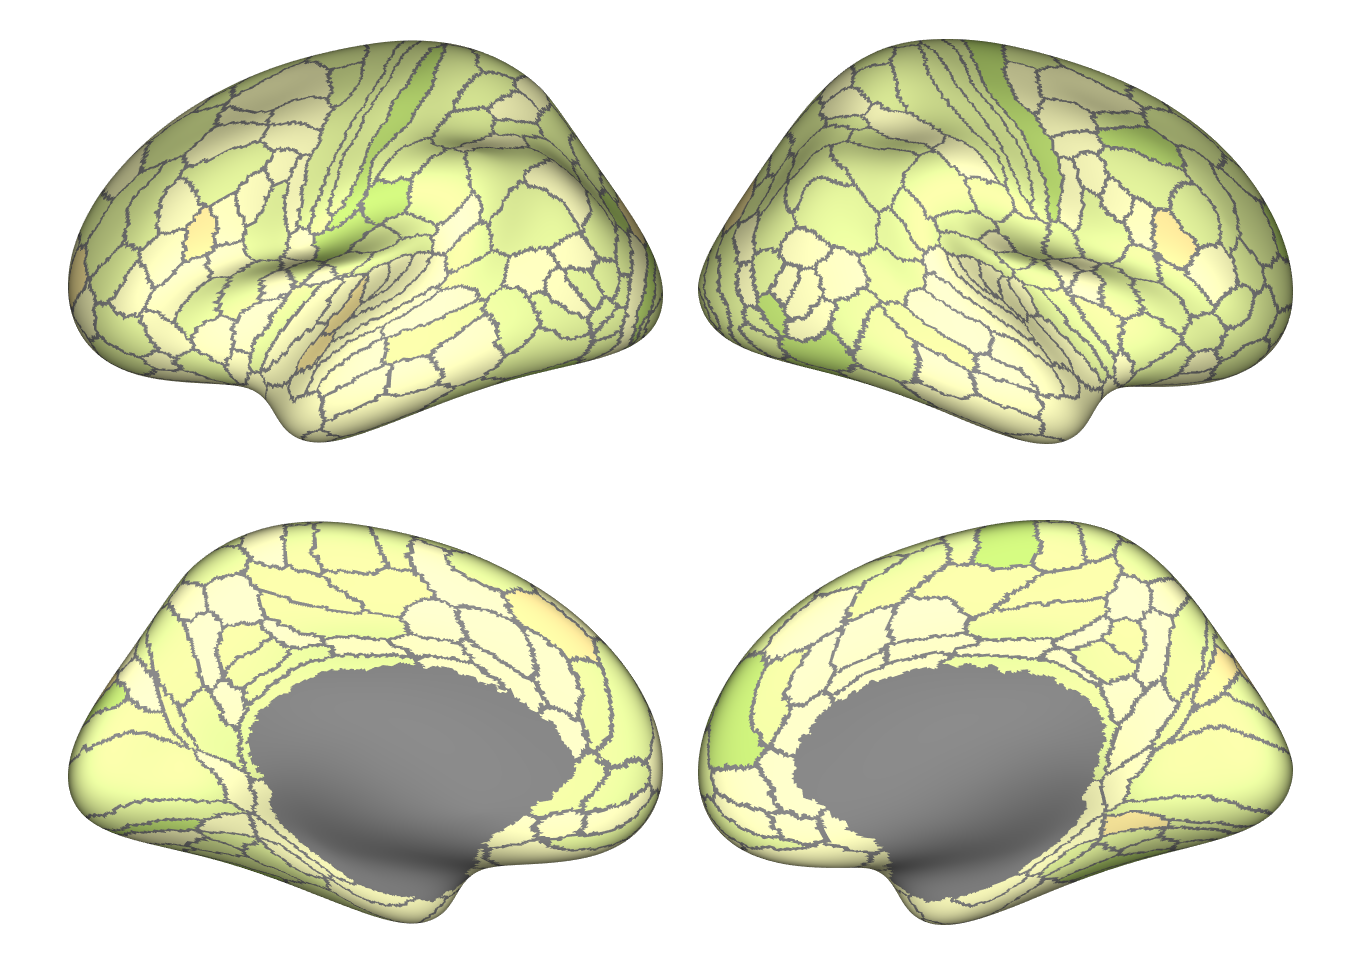

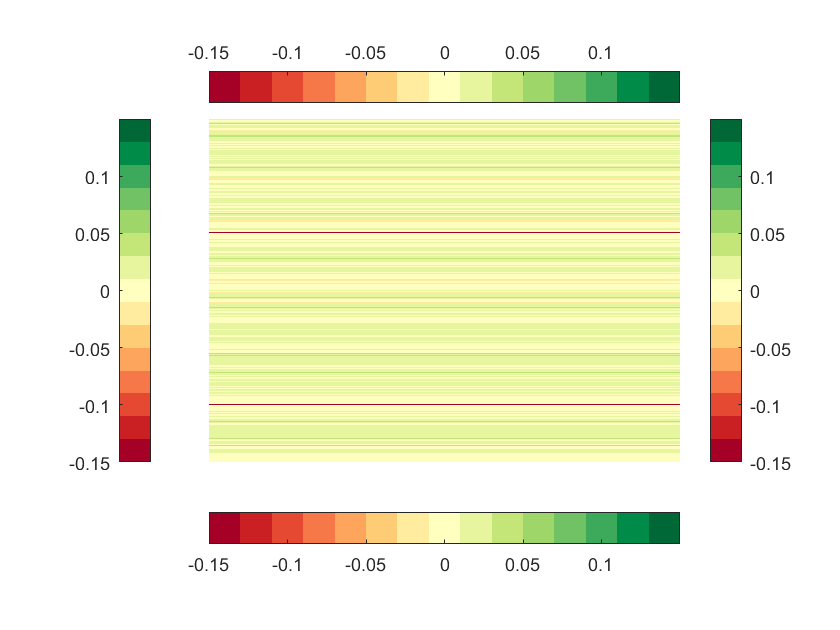

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'RdYlGn'),...
    'viewcMap',1, 'valRange', ([- 0.15 0.15]))